# Maximum Disturbance Duration

The longest duration of disturbance (in days).

## I/O

% Choose duration imagery.
[file, path] = uigetfile({'*.tif'}, 'Choose duration imagery.', 'Multiselect', 'on', '/home/dk/文档/Tutor/localSTMoran/(第二次挑选）衡阳盆地Landsat一致性数据生成结果/image/distDuration/');
[~, fileLength] = size(file);
info = geotiffinfo(strcat(path,char(file(1))));
duration = nan(info.Height,info.Width,fileLength);
maxIM = nan(info.Height,info.Width);
avgIM = nan(info.Height,info.Width);

for i = 1:fileLength
    [tempIM,R] = geotiffread(strcat(path,char(file(i))));
    tempIM(tempIM == 0 | tempIM < 0) = nan;
    duration(:,:,i) = tempIM;
end

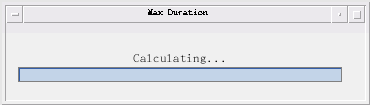

tic
f = waitbar(0,'Starting...','Name','Max Duration');
for m = 1:info.Height
    for n = 1:info.Width
        series = squeeze(duration(m,n,:));
        if sum(~isnan(series)) >= 1
            maxIM(m,n) = nanmax(series(:));
            avgIM(m,n) = nanmean(series(:));
        end
    end
    waitbar(m / info.Height,f,'Calculating...');
end

toc

时间已过 234.307780 秒。
